% Obtaining the rate equations and matrix
syms a(t) b(t) c(t) d(t) e(t) f(t)
K = [-1.5 0 0.2 0 0.4 0; 
    0.3 -1 0.4 0 0.6 0; 
    0 0.4 -2.1 0.4 0 0.02; 
    0 0 0.9 -0.41 0.2 0; 
    0.4 0.6 0 0.01 -2 0; 
    0.8 0 0.6 0 0.8 -0.02];
J = [a; b; c; d; e; f];
odes = diff(J) == K*J;

y0 = [1 0 0 0 0 0]';  %Initial conditions
tspan = 0:1:30;  %time span
[x,y] = ode45(@odesystem,tspan,y0);
[a,b] = ode23(@odesystem,tspan,y0);
[c,d] = ode113(@odesystem,tspan,y0);
fprintf("The overall sum of chemicals " + ...      
    "at t=0 is %d.",sum(y(1,:)))    %starting from 1 element as 

The overall sum of chemicals at t=0 is 1.

                         % there is no 0 index in a vector in MATLAB
fprintf("The overall sum of chemicals " + ...
    "at t=5 is %d.",sum(y(6,:)))

The overall sum of chemicals at t=5 is 1.000000e+00.

fprintf("The overall sum of chemicals " + ...
    "at t=10 is %d.",sum(y(11,:)))

The overall sum of chemicals at t=10 is 1.

fprintf("The overall sum of chemicals " + ...
    "at t=15 is %d.",sum(y(16,:)))

The overall sum of chemicals at t=15 is 1.000000e+00.

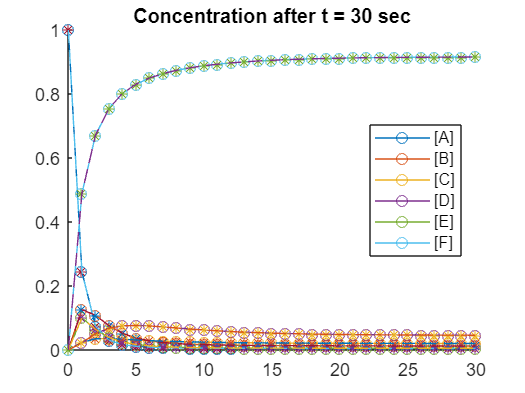

hold on
plot(x,y,"-o")
plot(a,b,"*")
plot(c,d,"--")
hold off
lgd = legend("[A]","[B]","[C]","[D]","[E]","[F]");
lgd.Location = "east";
title("Concentration after t = 30 sec");

[EV,ev] = eig(K)

EV =     0.3352   -0.2222    0.7690    0.1369    0.0041   -0.0323
    0.3104   -0.0858   -0.4280    0.5832    0.0127   -0.1049
   -0.5528   -0.6284   -0.2001    0.0324    0.0213   -0.1232
    0.2894    0.2380    0.1464   -0.4322    0.0491   -0.5273
   -0.5966    0.7012    0.1041    0.2882    0.0049   -0.0446
    0.2145   -0.0028   -0.3914   -0.6085    0.9985    0.8323


ev =    -2.5417         0         0         0         0         0
         0   -2.1968         0         0         0         0
         0         0   -1.4979         0         0         0
         0         0         0   -0.6108         0         0
         0         0         0         0   -0.0000         0
         0         0         0         0         0   -0.1827


syms c1 c2 c3 c4 c5 c6 t 
y = c1*EV(:,1)*exp(ev(1,1)*t) + c2*EV(:,2)*exp(ev(2,2)*t) + c3*EV(:,3)*exp(ev(3,3)*t) + c4*EV(:,4)*exp(ev(4,4)*t) + c5*EV(:,5)*exp(ev(5,5)*t) + c6*EV(:,6)*exp(ev(6,6)*t)

eqn1 = subs(y(1),t,0) == 1

$$eqn1 = \frac{3019430155027645\,c_{1}}{9007199254740992}-\frac{8004938628756055\,c_{2}}{36028797018963968}+\frac{865805562340975\,c_{3}}{1125899906842624}+\frac{1233368750078077\,c_{4}}{9007199254740992}+\frac{2384056125644435\,c_{5}}{576460752303423488}-\frac{4649976965289909\,c_{6}}{144115188075855872}=1$$

eqn2 = subs(y(2),t,0) == 0

$$eqn2 = \frac{2795716014219279\,c_{1}}{9007199254740992}-\frac{6185069168636807\,c_{2}}{72057594037927936}-\frac{1927574574362065\,c_{3}}{4503599627370496}+\frac{2626348029297831\,c_{4}}{4503599627370496}+\frac{3652706868962135\,c_{5}}{288230376151711744}-\frac{3780499530791989\,c_{6}}{36028797018963968}=0$$

eqn3 = subs(y(3),t,0) == 0

$$eqn3 = \frac{4667822070804671\,c_{4}}{144115188075855872}-\frac{2830030827525709\,c_{2}}{4503599627370496}-\frac{450557538295405\,c_{3}}{2251799813685248}-\frac{2489593575343043\,c_{1}}{4503599627370496}+\frac{3065176543827327\,c_{5}}{144115188075855872}-\frac{4439249345210053\,c_{6}}{36028797018963968}=0$$

eqn4 = subs(y(4),t,0) == 0

$$eqn4 = \frac{5212726972980487\,c_{1}}{18014398509481984}+\frac{8575907870508199\,c_{2}}{36028797018963968}+\frac{5274451197476565\,c_{3}}{36028797018963968}-\frac{7785035562276513\,c_{4}}{18014398509481984}+\frac{7071101850293165\,c_{5}}{144115188075855872}-\frac{2374597161506397\,c_{6}}{4503599627370496}=0$$

eqn5 = subs(y(5),t,0) == 0

$$eqn5 = \frac{6316119747729335\,c_{2}}{9007199254740992}-\frac{5373997445245979\,c_{1}}{9007199254740992}+\frac{937418283803829\,c_{3}}{9007199254740992}+\frac{2595820889632013\,c_{4}}{9007199254740992}+\frac{702464345878013\,c_{5}}{144115188075855872}-\frac{804309424070373\,c_{6}}{18014398509481984}=0$$

eqn6 = subs(y(6),t,0) == 0

$$eqn6 = \frac{3863349880389793\,c_{1}}{18014398509481984}-\frac{1642672450327847\,c_{2}}{576460752303423488}-\frac{3525096279995031\,c_{3}}{9007199254740992}-\frac{5481106796592763\,c_{4}}{9007199254740992}+\frac{8993401962899045\,c_{5}}{9007199254740992}+\frac{7496909814379137\,c_{6}}{9007199254740992}=0$$


sol = solve([eqn1,eqn2,eqn3,eqn4,eqn5,eqn6],[c1,c2,c3,c4,c5,c6])

sol = struct with fields:
    c1: 45240996841888928139275887353657197382384507252898717682490741299088132436119796620207094167909695488/410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821
    c2: -133661274588647053782777440010601853245938676891085557326148411581035296457373971092615232756513767424/410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821
    c3: 426038677177271839519968258778582400353897199222708246040984680339628286283082327644041128821575909376/410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821
    c4: 245713911381620223897719971647507859425308397584874331963552430150347710960836311630193352956618735616/410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821
    c5: 376329488711157158704140525789303421465455584355864548902866704375658729288240020672832050420766474240/4103818

cc1 = sol.c1

$$cc1 = \frac{45240996841888928139275887353657197382384507252898717682490741299088132436119796620207094167909695488}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}$$

cc2 = sol.c2

$$cc2 = -\frac{133661274588647053782777440010601853245938676891085557326148411581035296457373971092615232756513767424}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}$$

cc3 = sol.c3

$$cc3 = \frac{426038677177271839519968258778582400353897199222708246040984680339628286283082327644041128821575909376}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}$$

cc4 = sol.c4

$$cc4 = \frac{245713911381620223897719971647507859425308397584874331963552430150347710960836311630193352956618735616}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}$$

cc5 = sol.c5

$$cc5 = \frac{376329488711157158704140525789303421465455584355864548902866704375658729288240020672832050420766474240}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}$$

cc6 = sol.c6

$$cc6 = -\frac{83593424967694037449194336759432468398856006638073639187090455363757733152217730669134667309111050240}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}$$



y = subs(y,[c1,c2,c3,c4,c5,c6],[cc1,cc2,cc3,cc4,cc5,cc6])

$$ans = \frac{666648259860330074821958202495150537759235783272822760387933683978625397271215709589548\,{\mathrm{e}}^{-\frac{687731942786275\,t}{1125899906842624}}}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}-\frac{5022759635085908074189729716613994335004334785044068665548293728294396979907587466064\,{\mathrm{e}}^{-\frac{715433899010649\,t}{281474976710656}}}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}+\frac{410381899456306491989787385342644555047314575876004562542753459680721316926287654777097336013118114150\,{\mathrm{e}}^{-\frac{7945415139583869\,t}{649037107316853453566312041152512}}}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}-\frac{247679602252729960601459897858428904670543521899083199789334988896203848918166144613965\,{\mathrm{e}}^{-\frac{3292102366257897\,t}{18014398509481984}}}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}+\frac{303975474974717773372254916743570289659445725010215112832681213337367987045058985617928\,{\mathrm{e}}^{-\frac{1236681497986487\,t}{562949953421312}}}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}-\frac{508472794941780245596658492009929464639438877653811315597896548906909250658340828873776\,{\mathrm{e}}^{-\frac{421622353102671\,t}{281474976710656}}}{410381899456306701438365390794378476952314229624468336237527404780010484761353439362985095873252367821}$$

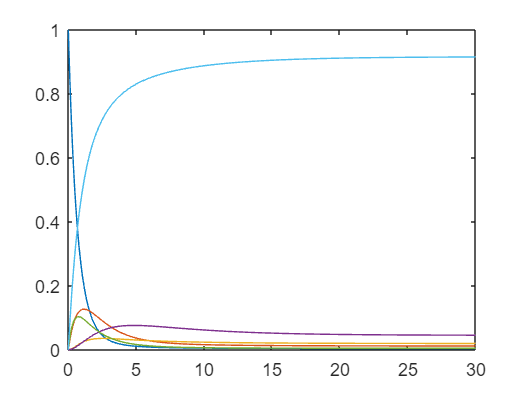

fplot(y,[0,30])
hold off